cd /Volumes/yaochen/Active/Yao/Microscopy/FLIM/AnalyzedData/HEK_5HTSensor/yc5HTSensor008(HEK_5HTSensor_5HT)-Analyzed/Analysis_PM_offset0
load('yc5HTSensor008_Analysis2022-11-09.mat')

masks = stateYao.images.I_ROI_stack;
results = stateYao.Results;
Yao_GUI_ReviseROIsBasedOnCoordinates
masks2 = stateYao.images.I_ROI_stack;
results2 = stateYao.Results;

intensity_all = {};
lifetime_all = {};

for i = 1:size(stateYao.AcqTime, 2) % cycle position number
    intensity = zeros(size(stateYao.ROI{i},1), size(stateYao.ROI{i}{1},2));
    lifetime = zeros(size(stateYao.ROI{i},1), size(stateYao.ROI{i}{1},2));
    for j = 1:size(stateYao.ROI{i}{1},2) % roi number
        for k = 1:size(stateYao.ROI{i},1) % acq number
            rgbLifetimes = stateYao.images.origData.rgbLifetimes{i}(:,:,:,k);
            lifetimeMaps = stateYao.images.origData.lifetimeMaps{i}(:,:,k);
            projects = stateYao.images.origData.projects{i}(:,:,k);

            orig_mask1 = logical(masks{i}{k}(:,:,j));
            orig_mask2 = logical(masks2{i}{k}(:,:,j));

            intensity(k, j) = Yao_calc_Projection(projects, orig_mask2);
            lifetime(k, j) = Yao_calc_Lifetime(projects, lifetimeMaps, orig_mask2);



            mask1 = boundarymask(logical(masks{i}{k}(:,:,j)));
            mask2 = boundarymask(logical(masks2{i}{k}(:,:,j)));
            B1 = imoverlay(rgbLifetimes, mask1);
            B2 = imoverlay(rgbLifetimes, mask2);

            f = figure('Position', [10 10 1200 500], 'visible','off');
            subplot(1,2,1)
            image(B1)
            subplot(1,2,2)
            image(B2)
            title(['cycle position ', num2str(i), ', cell ', num2str(j), ', acq ', num2str(k)])

            figure_name = ['c', num2str(i), 'cell', num2str(j), '_', num2str(k), '.png'];
            saveas(f, figure_name)
        end
    end

    intensity_all{i} = intensity;
    lifetime_all{i} = lifetime;
end









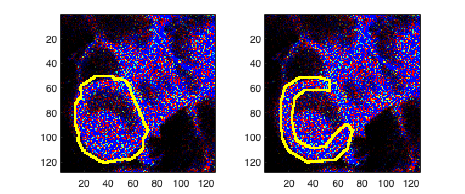

figure('Position', [10 10 1200 500])
subplot(1,2,1)
image(B1)
subplot(1,2,2)
image(B2)